GBN_st.name='GBN';
GBN_st.lat=39.0052;
GBN_st.lon=-114.216;
GBN_st.alt=2065;
GBN_st.env='Mt';
GBN_st.footp='DE';


GBN_rd=read_betsy('GBN_head',GBN_st.name);

datevec(GBN_rd.Time(1))

ans =         2008           1           2           0           0           0

datevec(GBN_rd.Time(end))

ans =         2019           1           1           0           0           0

prctile(GBN_rd.U_S,[5 50 95])

ans =    14.2750   41.2975   79.9725

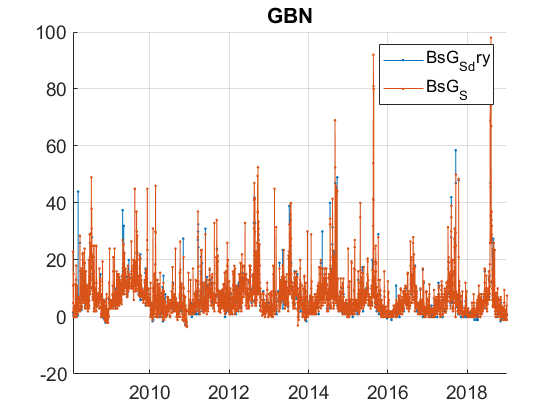

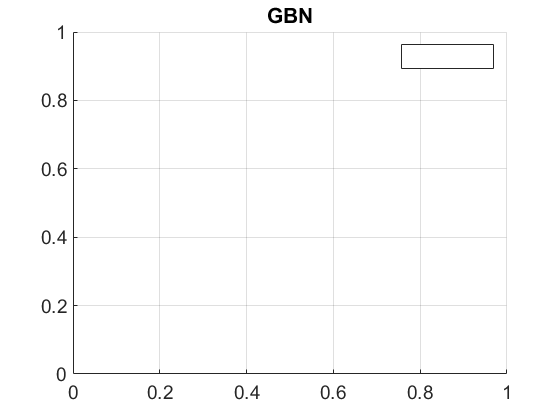

plotFigControl(GBN_rd,GBN_st.name);

% 2 size cut, ok
% sc: ok, max in summer, few negatives



% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% GBN_cal=compute_exp_SSA(GBN_rd,lambdaSC, lambdaAE);
% plotFigControl_cal(GBN_cal,GBN_st.name);

%Questions:
%problems:
%sca: 2009 has higher values, a little bit strange, can you control ?

GBN_tr=GBN_rd;
GBN_tr.y=year(GBN_tr.Time);

% begin at the beginning of a year: 2008
%end  2018
P=timerange('2008-01-01','2019-01-01');
GBN_tr=GBN_tr(P,:);
names=fieldnames(GBN_tr);
c= startsWith(names,'T_') ;
N=names(c);
for i=1:length(N)
    GBN_tr.(N{i})=[];
end
GBN_tr.T=[];
%try without 2009: it change completely the trend
% due to the figure send by PI, delete 2009: no trend
%GBN_tr2=GBN_tr;

%difficult to decide, but I finally let 2009 and the ss negative trend
%correspond then to the stations in proximity. 
% % % P2=timerange('2009-01-01','2010-01-01');
% % % GBN_tr.BsG_S(P2)=NaN;
% % % GBN_tr.BsG_S_dry(P2)=NaN;
%GBN_st2=GBN_st; GBN_st2.name='GBN2';

GBN_result= all_trend_STN(GBN_tr,GBN_st); 
%GBN_result2= all_trend_STN(GBN_tr2,GBN_st2); 

GBN_result_D=GBN_result;